Custom filter generation:

Procedural filter test

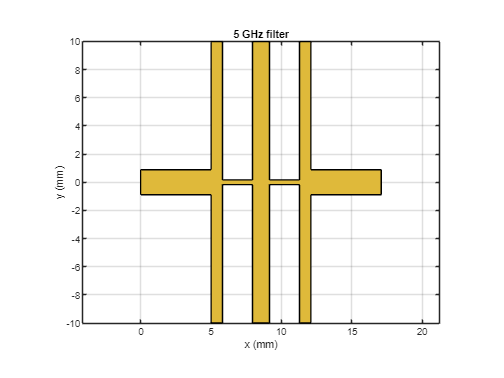

clc
clear all
close all

met = metal('copper');
met.Thickness = 18e-06; % 1/2 oz copper (18um)
sub = dielectric("RO4350B");
sub.Thickness = 0.76e-3;

fcl = 1.5e9; % first corner
fch = 8e9; % high corner

% Meas in mm
connector_length = 5e-3; % 50ohm microstrip length (to connect the circuit)

% 0.5 dB equal ripple chebishew 5
gn5 = [1 1.7058 1.2296 2.5408 1.2296 1.7058 1];
% 0.5 dB equal ripple chebishew 6
gn6 = [1 1.7254 1.2479 2.6064 1.3137 2.4758 0.8696 1.9841];
% 0.5 dB equal ripple chebishew 7
gn7 = [1 1.7372 1.2583 2.6381 1.3444 2.6381 1.2583 1.7372 1];
% max flat 5
gnmf5 = [1 0.9303 0.4577 0.3312 0.2090 0.0718 1];

% Widths/Impedances
wdt = [1.77 20 0.33] * 1e-3;
imp = [50 7.21 109.77];
%tpd = [55.1987 60.4582 52.1777];
l0 = [2.7613 0.4358 5.7273]*100*1e-9; % v tabeli nh/cm
c0 = [1.1034 8.3869 0.4754]*100*1e-12; % v tabeli pf/cm
betl = 2*pi*fcl*sqrt(l0.*c0);
beth = 2*pi*fch*sqrt(l0.*c0);

[filterl, pcbl, lengthsl, widthsl, L_totl, W_totl] = gen_filt_poly(gn7, wdt, imp, betl, connector_length, met, sub);
[filterh, pcbh, lengthsh, widthsh, L_toth, W_toth] = gen_filt_poly(gn5, wdt, imp, beth, connector_length, met, sub);
[filterh1, pcbh1, lengthsh1, widthsh1, L_toth1, W_toth1] = gen_filt_poly(gn6, wdt, imp, beth, connector_length, met, sub);

%show(filterl);
%title("1,5 GHz filter")
%show(pcbl);
%title("1,5 GHz filter PCB")

show(filterh);
title("5 GHz filter")

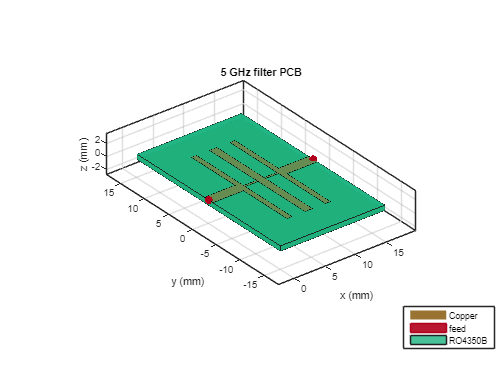

show(pcbh);
title("5 GHz filter PCB")

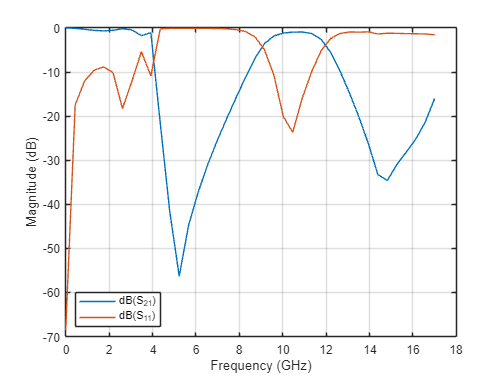


% ------------
% 
%S = sparameters('test2/sito_1-5GHz_7stopnje.S2P');
sparh = sparameters(pcbh,linspace(1e6,17e9,40));

%rfplot(S, 2, 1);
%hold on
rfplot(sparh,[2 1], 1);
legend(Location="southwest");

rfwrite(sparh,'filthigh5theory.s2p')

%translate(filterh, [L_totl 0 0])
%filtersum = filterl + filterh;
%translate(filterh, [-L_totl 0 0])
%show(filtersum);
%L_tot = L_totl + L_toth;
%W_tot = W_totl;
%gnd = traceRectangular(Length = L_tot, Width = W_tot, Center = [L_tot/2,0]);

%pcb = pcbComponent(Conductor=met);
%pcb.BoardShape = gnd;
%pcb.BoardThickness = 0.76e-3;
%pcb.Layers ={filtersum,sub,gnd};
%pcb.FeedDiameter = wdt(1)/2;
%pcb.FeedLocations = [0 0 1 3;L_tot 0 1 3];
%figure;
%show(pcb);
%sparl = sparameters(pcbl,linspace(1e6,17e9,40));
%figure;
%rfplot(sparl,[2 1], 1);
%legend(Location="southwest")
%rfwrite(sparl,'filtlow7.s2p')
%rfwrite(sparh,'filthigh5MF.s2p')